# Test by Mikołaj Suchoń

### Task 1

clear
load('question_group_2.mat')
N1=length(Pulse)

N1 = 1000

N2=length(Response)

N2 = 50000

dt=1/fs

dt = 5.0000e-08

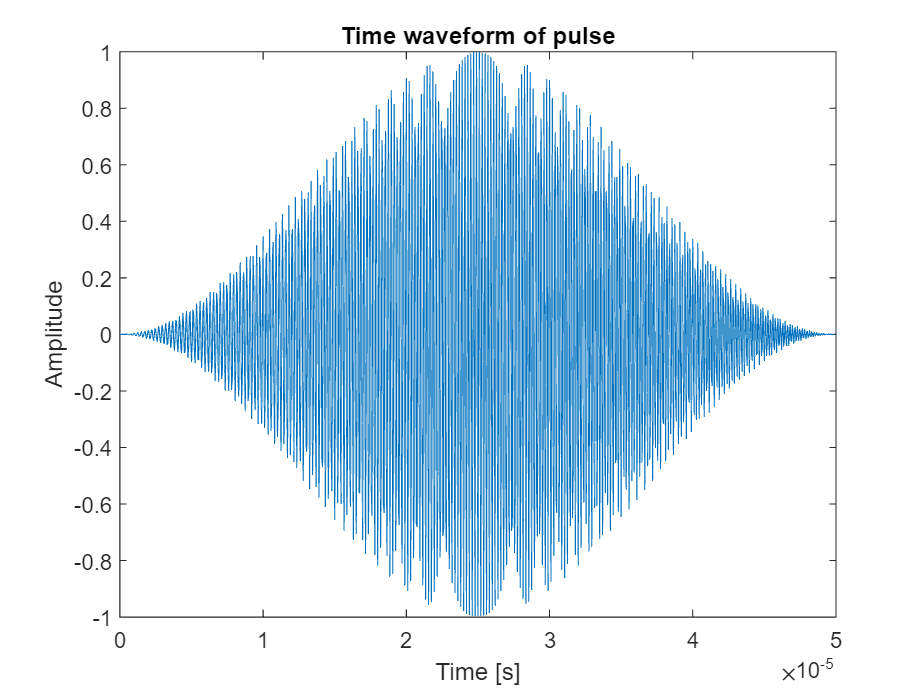

t1=(0:N1-1)*dt;
t2=(0:N2-1)*dt;
plot(t1,Pulse)
title('Time waveform of pulse')
xlabel('Time [s]')
ylabel('Amplitude')

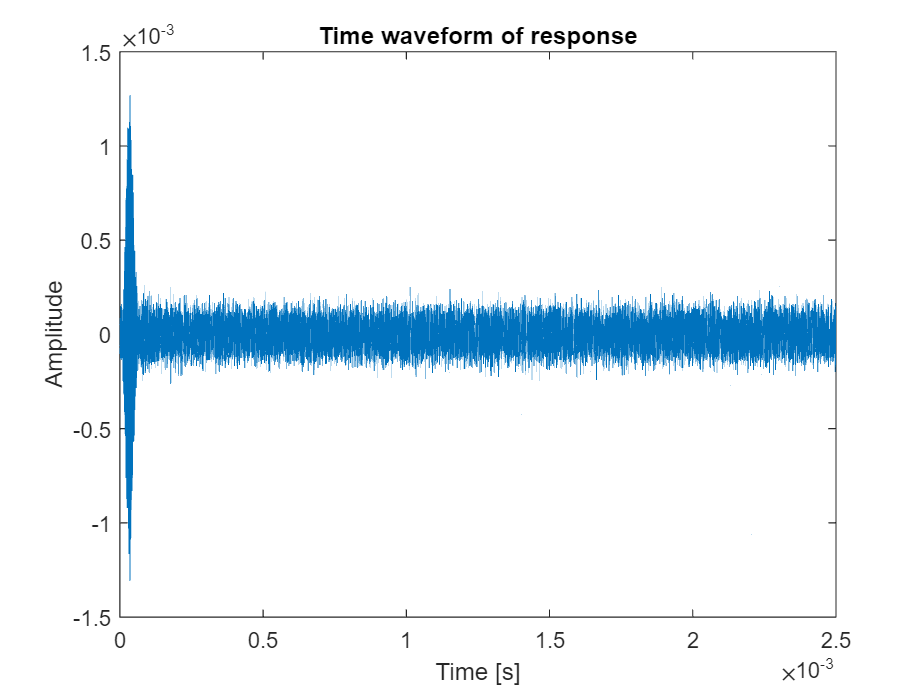

plot(t2,Response)
title('Time waveform of response')
xlabel('Time [s]')
ylabel('Amplitude')

### Task 2

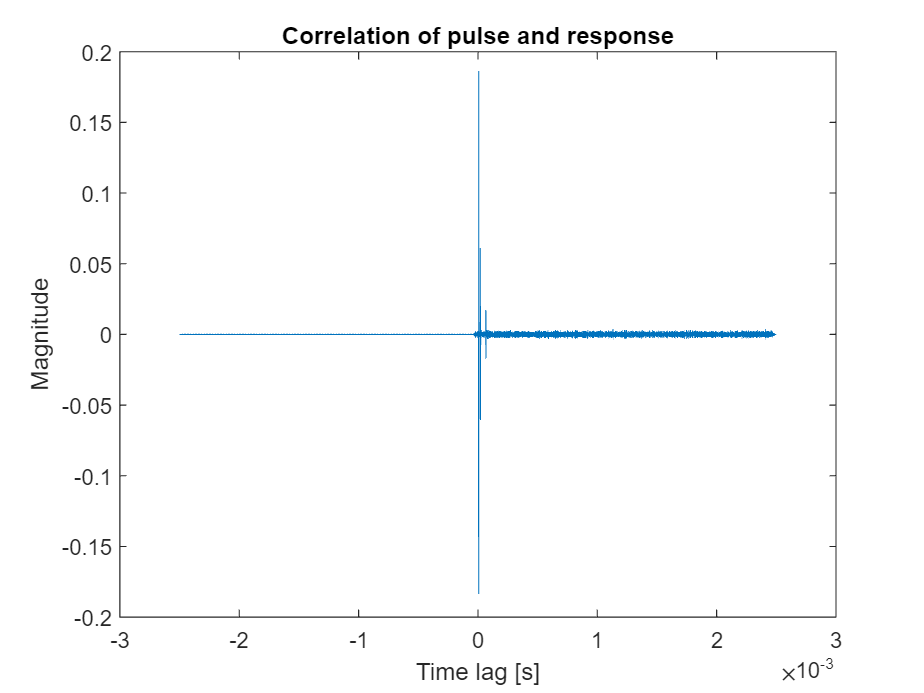

[yc,lag] = xcorr(Response,Pulse);
tc = lag/fs;
plot(tc,yc)
title('Correlation of pulse and response')
xlabel('Time lag [s]')
ylabel('Magnitude')

The biggest peak is at a time lag of 6.65e-6

TimeLag=6.65e-6

TimeLag = 6.6500e-06

We asume the speed of electromagnetic waves to be 299,792,458 m/s

v=299792458;
D1=v*TimeLag

D1 = 1.9936e+03

The first distance is 1993.6m away ~2km

TimeLag2=2e-5

TimeLag2 = 2.0000e-05

TimeLag3=6.65e-5

TimeLag3 = 6.6500e-05

D2=v*TimeLag2

D2 = 5.9958e+03

D3=v*TimeLag3

D3 = 1.9936e+04

The second distance is 5.996km and the third is 19.936km

Task 3

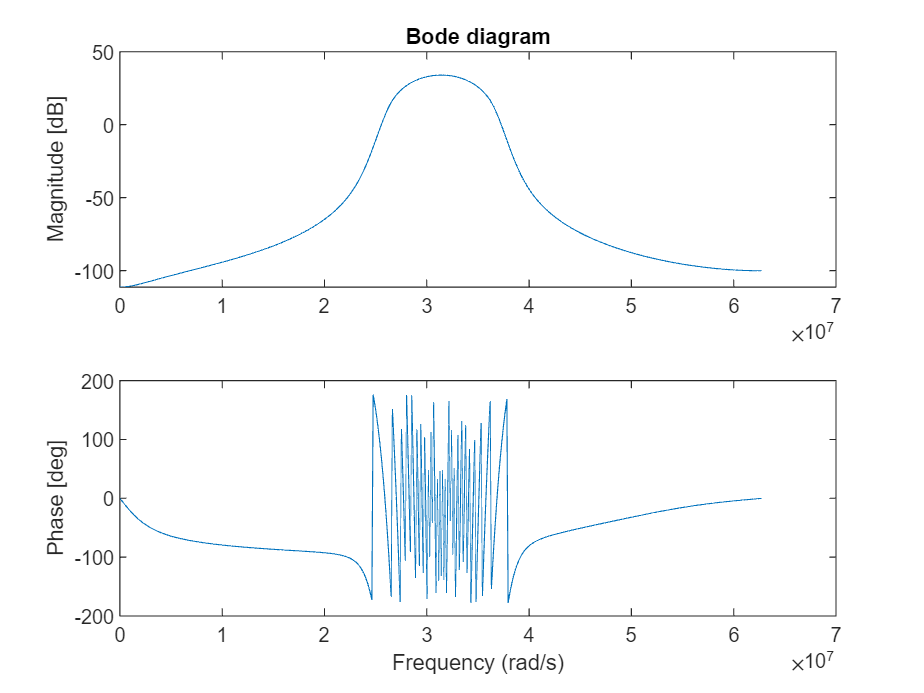

ownBode(Pulse,fs)

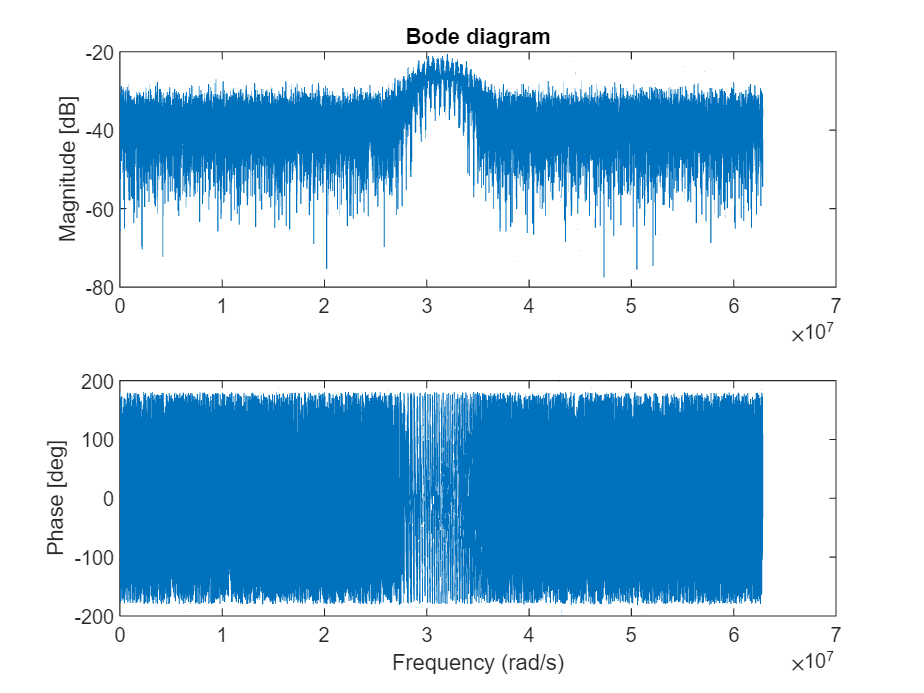

ownBode(Response,fs)

w1=2.55*10e7 rad/s

w2=3.65*10e7 rad/s

Wr=3.15*10e7 rad/s

w1=2.55*10e7;
w2=3.65*10e7;
Wr=3.15*10e7;
epsi=(w2-w1)/(2*Wr);

The bandwith of the pulse signal is equal to 0.1746 rad/s.

centralFreq=Wr/(2*pi);

Central frequency is equal to 5.0134e07 Hz.

function ownBode(x1,fs)

N=length(x1);
H=fft(x1);
H_mag=abs(H);
df=fs/N;
f=(0:df:fs-1);
figure
title('Bode diagram')
subplot(211)
plot(f(1:floor(N/2))*2*pi,20*log10(H_mag(1:floor(N/2))))
title('Bode diagram')


ylabel('Magnitude [dB]')
subplot(212)
H_phase=angle(H);
plot(f(1:floor(N/2))*2*pi,rad2deg(H_phase(1:floor(N/2))))


ylabel('Phase [deg]')
xlabel('Frequency (rad/s)')
end